d1_PxP = 42; a2_PxP = 105; a3_PxP = 105; a4_PxP = 110;
Link_PxP(1) = Link([0 d1_PxP 0 -pi/2]);
Link_PxP(2) = Link([0 0 a2_PxP 0]);
Link_PxP(3) = Link([0 0 a3_PxP 0]);
Link_PxP(4) = Link([0 0 a4_PxP 0]);
plotOptions = {'noa', 'jaxes', 'tilesize', 2, 'ortho'};
PhantomX = SerialLink(Link_PxP, 'name', 'PhantomX Pincher Robot', 'plotopt', plotOptions)

 
PhantomX = 
 
PhantomX Pincher Robot (4 axis, RRRR, stdDH, fastRNE)            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         42|          0|     -1.571|          0|
|  2|         q2|          0|        105|          0|     -1.571|
|  3|         q3|          0|        105|          0|          0|
|  4|         q4|          0|        110|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1         

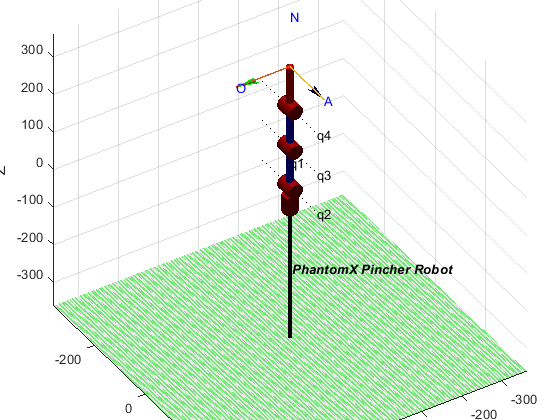

q_home = [0 0 0 0];
figure(1)
PhantomX.plot(q_home)

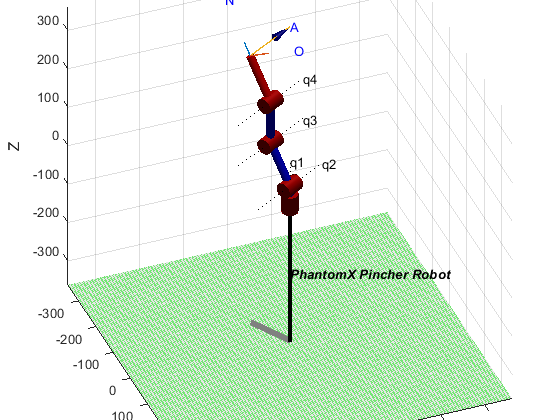

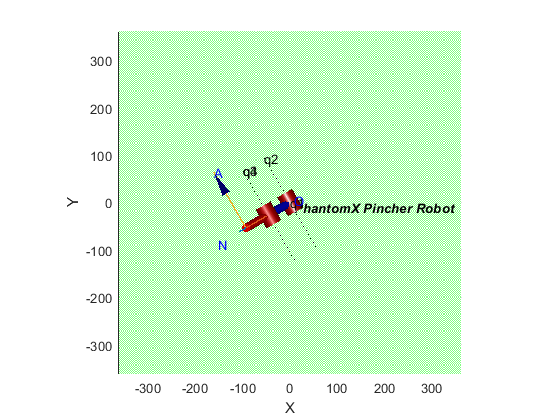

q_objective = [pi/6 -pi/6 pi/6 -pi/6];
figure(2)
PhantomX.plot(q_objective)